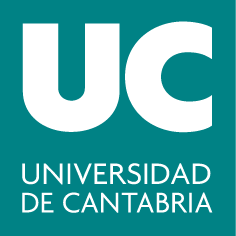

*Dpto. Matemática Aplicada y Ciencias de la Computación*

**Métodos Matemáticos en la Ingeniería**

**Bloque II: Métodos Numéricos**

# **4. Resolución numérica de sistemas lineales**

## Introducción

Este tema considera 2 tipos de problemas:

-  Resolución de sistemas lineales Ax=b

- Cálculo de valores y vectores propios $\(Ap=\lambda p\)$, con$ \(\lambda\in\mathbb{R}\) o \(\mathbb{C}\)$

#### Antecedentes matemáticos

**Matriz** es un conjunto bidimensional de números: 

	 
$$A = \left( \matrix{a_{11} & a_{12} & \cdots & a_{1n} \cr a_{21} & a_{22} & \cdots & a_{2n} \cr \vdots & \vdots & \ddots & \vdots \cr a_{m1} & a_{m2} & \cdots & a_{mn}} \right)_{m \times n}$$


- Los elementos individuales de una matriz $$A_{m\times n}$$, se denotan por $$a_{ij}$$, donde $$i$$ indica la fila, y  $$j$$ -  la columna.

- Si el número de filas y el de columnas coinciden, $$m=n$$, se dice que la matriz es cuadrada del orden $$n$$.

- La matriz **traspuesta** de una matriz $$A$$ se obtiene al intercambiar sus filas por sus columnas. Se denota como $$A^T$ o $A^t$$.

**	Ejemplo:**

% Las comas separan columnas, el punto y coma inicia una nueva fila.
A = [1, 2; 3, 4; 5, 6]

% El editor de MATLAB entiende que un salto de línea dentro de los corchetes
% significa una nueva fila:
A = [1 2
     3 4
     5 6]

At = A'      % Para matrices reales, es una traspuesta simple.

% para obtener el número de filas y de columnas:
dimensiones = size(A)     % Devuelve el vector [3 2]

% otra opción:
[filas, columnas] = size(At);
fprintf('La matriz At tiene %d filas y %d columnas.\n', filas, columnas);


Dada una matriz $ $M=(a_{ij})_{m \times n}$$, y una matriz  $$N=(b_{hk})_{n \times p}$$, llamamos **matriz producto** de $$M$$ por $$N$$ y lo representaremos por $ $MN$$ a la matriz $$m \times p$$ cuyo elemento $$c_{rs}$$ es $\[ c_{rs} = \sum_{k=1}^n a_{rk}b_{ks}. \]$

% M es una matriz de 2 filas y 3 columnas (2x3)
M = [1 2 3; 4 5 6]

% N es una matriz de 3 filas y 3 columnas (3x3)
% Usamos magic(3) para generar una matriz de ejemplo rápidamente.
N = magic(3)

% Obtenemos las dimensiones de ambas matrices
[filas_M, columnas_M] = size(M)
[filas_N, columnas_N] = size(N)

% como columnas_M = filas_N, podemos calcular el producto:
MN = M*N

#### Matrices Especiales

- Matriz nula: Es una matriz de cualquier dimensión en la que todos sus elementos son cero. Se denota por  $$\mathbf{0}_{m \times n}$$.

O = zeros(2,3) % matriz nula 2x3

- Matriz diagonal: Es una matriz cuadrada en la que todos los elementos fuera de la diagonal principal son cero. Es decir, si $$A = (a_{ij})$$ es una matriz $$n \times n$$, es diagonal si $$a_{ij} = 0$$ para todo $$i \neq j$$.

D = diag([1,2,3]) % matriz diagonal 
d = diag(D)  % [vector] diagonal de la matriz dada

- Matriz identidad: Es una matriz diagonal en la que todos los elementos de la diagonal principal son iguales a 1. Se denota por $$I$$ o $$I_n$$, donde $$n$$ es la dimensión de la matriz. 

I = eye (3) % matriz identidad 3x3

- Matriz inversa: Dada una matriz cuadrada $$A$$, su inversa, denotada como $$A^{-1}$$, es la única matriz que cumple la siguiente condición $	\[
	A A^{-1} = A^{-1} A = I_n
	\]$

A = magic(3) % matriz cuadrada 3x3
A_inv = inv (A) % inversa

% calculamos el producto A*A_inv para comprobar:
A*A_inv % es una matriz identidad

Una matriz A se dice

- **simétrica**, si $$A = A^t$$.

- **ortogonal**, si $$A^{-1} = A^t$$.

- **singular**, si $$\det A = 0$$ (no existe $$A^{-1}$$).

Preguntas:

- ¿Toda matriz diagonal es también una matriz simétrica? ¿Por qué?

-  Si una matriz A es ortogonal, ¿puede ser también una matriz singular?

** Ejercicio (4.1): **  Dadas las siguientes matrices:


$$A = 
	 \left( \matrix{
		5 & 1 & 2 \cr
		1 & 3 & 0 \cr
		2 & 0 & 4
}\right),
	\quad
	B = 
	\left( \matrix{
		2 & 0 & 0 \cr
		0 & -1 & 0 \cr
		0 & 0 & 8
	}\right),
	\quad
	C = 
	\left( \matrix{
		1 & 2 & 3 \cr 
		4 & 5 & 6 \cr
		7 & 8 & 9
	}\right),
	\quad
	D = 
	\left( \matrix{
		2 & -3 & 1 \cr
		1 & 1 & 1 \cr
		4 & -6 & 2
	}\right)$$


	Indica si son simétricas, diagonales, singulares, ortogonales  o ninguna de las anteriores (una matriz puede pertenecer a más de una categoría).

Para comprobar los resultados:

A = [5 1 2; 
    1 3 0;
    2 0 4]

At = A'; % calculamos la traspuesta 
if At == A
    fprintf("A es simétrica\n")
else
   fprintf("A no es simétrica\n") 
end

% Verificamos si la matriz A es diagonal:
d = diag(A); % vector-diagonal de la matriz A
D = diag(d); % matriz diagonal del vector d
if D == A
    fprintf("A es diagonal\n");
else
    fprintf("A no es diagonal\n");
end

% Verificamos si la matriz A es singualar:
if det(A) == 0
    fprintf("A es singular y por tanto no puede ser ortogonal\n");
else
    fprintf("A no es singular\n");
    if inv(A) == At
        fprintf("A es ortogonal\n");
    else
        fprintf("A no es ortogonal\n");
    end

end

#### Norma matricial

Una **norma matricial **en el espacio $$\mathbb{R}^{n \times m}$$ se define como una función $$||\cdot|| : \mathbb{R}^{n \times m} \to \mathbb{R}$$ que cumple las siguientes propiedades:

- $ $||A|| \ge 0$$ para todo $$A \in \mathbb{R}^{n \times m}$$.

- $ $||A|| = 0$$	 si, y sólo si, A es la matriz nula.

- $$||\alpha A|| = |\alpha| ||A||$ $para todo $$\alpha \in \mathbb{R}$ y $A \in \mathbb{R}^{n \times m}$$.

- 
$$ $||A + B|| \le ||A|| + ||B||$ para todo $A, B \in \mathbb{R}^{n \times m}$.$$


Si el conjunto de matrices contiene sólo matrices cuadradas, se suele añadir la propiedad: $\[ ||A \cdot B|| \le ||A|| \cdot ||B|| \text{ para todo } A, B \in \mathbb{R}^{n \times n} \]$

-  **Norma 1**: $$ ||A||_1 = \max_{1 \le j \le n} \sum_{i=1}^{m} |a_{ij}| $$

- ** Norma infinito: **$$ ||A||_\infty = \max_{1 \le i \le m} \sum_{j=1}^{n} |a_{ij}| $$

**Ejercicio (4.2): **Para cada una de las siguientes matrices, calcula $$||\cdot||_1$ y $||\cdot||_\infty$$:

		
$$		A = 
		\left( \matrix{
			1 & -7 & 3 \cr
			-5 & 2 & -1 
}\right),
		\quad 
		B = 
		\left( \matrix{
			3 & 0 & -2 \cr
			1 & 5 & 4 \cr
			-6 & 1 & 0
} \right),
		\quad 
		C = 		\left( \matrix{
			8 \cr
			-1 \cr
			3
	}\right) ,
		\quad 
		D = 		\left( \matrix{
			4 & -2 & 0 & -5
		}\right)
		$$


Solución:


$$		 $||A||_1 = \max(|1|+|-5|, |-7|+|2|, |3|+|-1|) = \max(6, 9, 4) = {9}$
$$



$$		 $||A||_\infty = \max(|1|+|-7|+|3|, |-5|+|2|+|-1|) = \max(11, 8) = {11}$$$


A = [1 -7 3 
    -5 2 -1]
A_norm1 = norm(A,1)
A_norm_inf = norm(A,inf)


Matriz B:

% escribe aquí el código para calcular las normas:





$$  $||B||_1 = 10$,  $||B||_\infty = 10$$$


Matriz C: 

% escribe aquí el código para calcular las normas:





$$$||C||_1 = {12}$,   $||C||_\infty = {8}$$$


Matriz D:

% escribe aquí el código para calcular las normas:






$$  $||D||_1 = {5}$,  $\;||D||_\infty ={11}$$$


**Ejercicio (4.3): **Responde a las siguientes preguntas, justificando tu respuesta.

-  Para la matriz identidad $$I_n$$ de tamaño $$n \times n$$, ¿cuál es el valor de $$||I_n||_1$$ y $$||I_n||_\infty$$?

- ¿Es siempre cierto que para cualquier matriz cuadrada A, se cumple que $$||A||_1 = ||A^t||_\infty$$? Justifica tu respuesta.

- Construye una matriz G de $$2 \times 2$$ que no sea simétrica, pero para la cual se cumpla que $$||G||_1 = ||G||_\infty$$.

% escribe aquí el código:





#### Radio espectral

Para una matriz cuadrada A, un **autovalor** $$\lambda$$ y su autovector asociado $$\mathbf{v}$$ $$(\mathbf{v} \neq 0$)$ satisfacen: $\[  A\mathbf{v} = \lambda\mathbf{v} \]$.

El autovalor $$\lambda$$ nos dice cómo la matriz A "estira" o "contrae" el vector $$\mathbf{v}$ $sin cambiar su dirección.

	El** radio espectral** de A es el máximo de los valores absolutos de todos sus autovalores: $\[ \rho(A) = \max_i |\lambda_i| \]$

Visualmente, si dibujamos todos los autovalores en el plano complejo, $$\rho(A)$$ es el radio del círculo más pequeño centrado en el origen que los contiene a todos.	

Si $$A_{n\times n}$$ es una matriz cuadrada, entonces

- 
$$$\rho(A) \leq \|{A}\|$$$


- 
$$$\|A\|_2 = \left[\rho (A^t A)\right]^{1/2}$$$


-  Si A es una matriz real y simétrica, entonces$ $\rho(A) = \|{A}\|_2$$.

## Sistemas lineales

Sistema de ecuaciones lineales:

		
$$\[
		\begin{cases}
			a_{11}x_1 + a_{12}x_2 + \dots + a_{1n}x_n = b_1 \\
			a_{21}x_1 + a_{22}x_2 + \dots + a_{2n}x_n = b_2 \\
			\vdots \\
			a_{m1}x_1 + a_{m2}x_2 + \dots + a_{mn}x_n = b_m
		\end{cases}
		\]$$


Estos sistemas de ecuaciones pueden ser expresados de forma matricial

		
$$\[ Ax = b \]$$


donde $$A = \{a_{ij}\}_{j=1, i=1}^{n,m}$, $b = \{b_i\}_{i=1}^m$ y $x = \{x_j\}_{j=1}^n$$.

 La matriz completa $$\bar A = (A|b)$$ se le llama **matriz ampliada**.

#### Teorema de Rouché-Frobenius

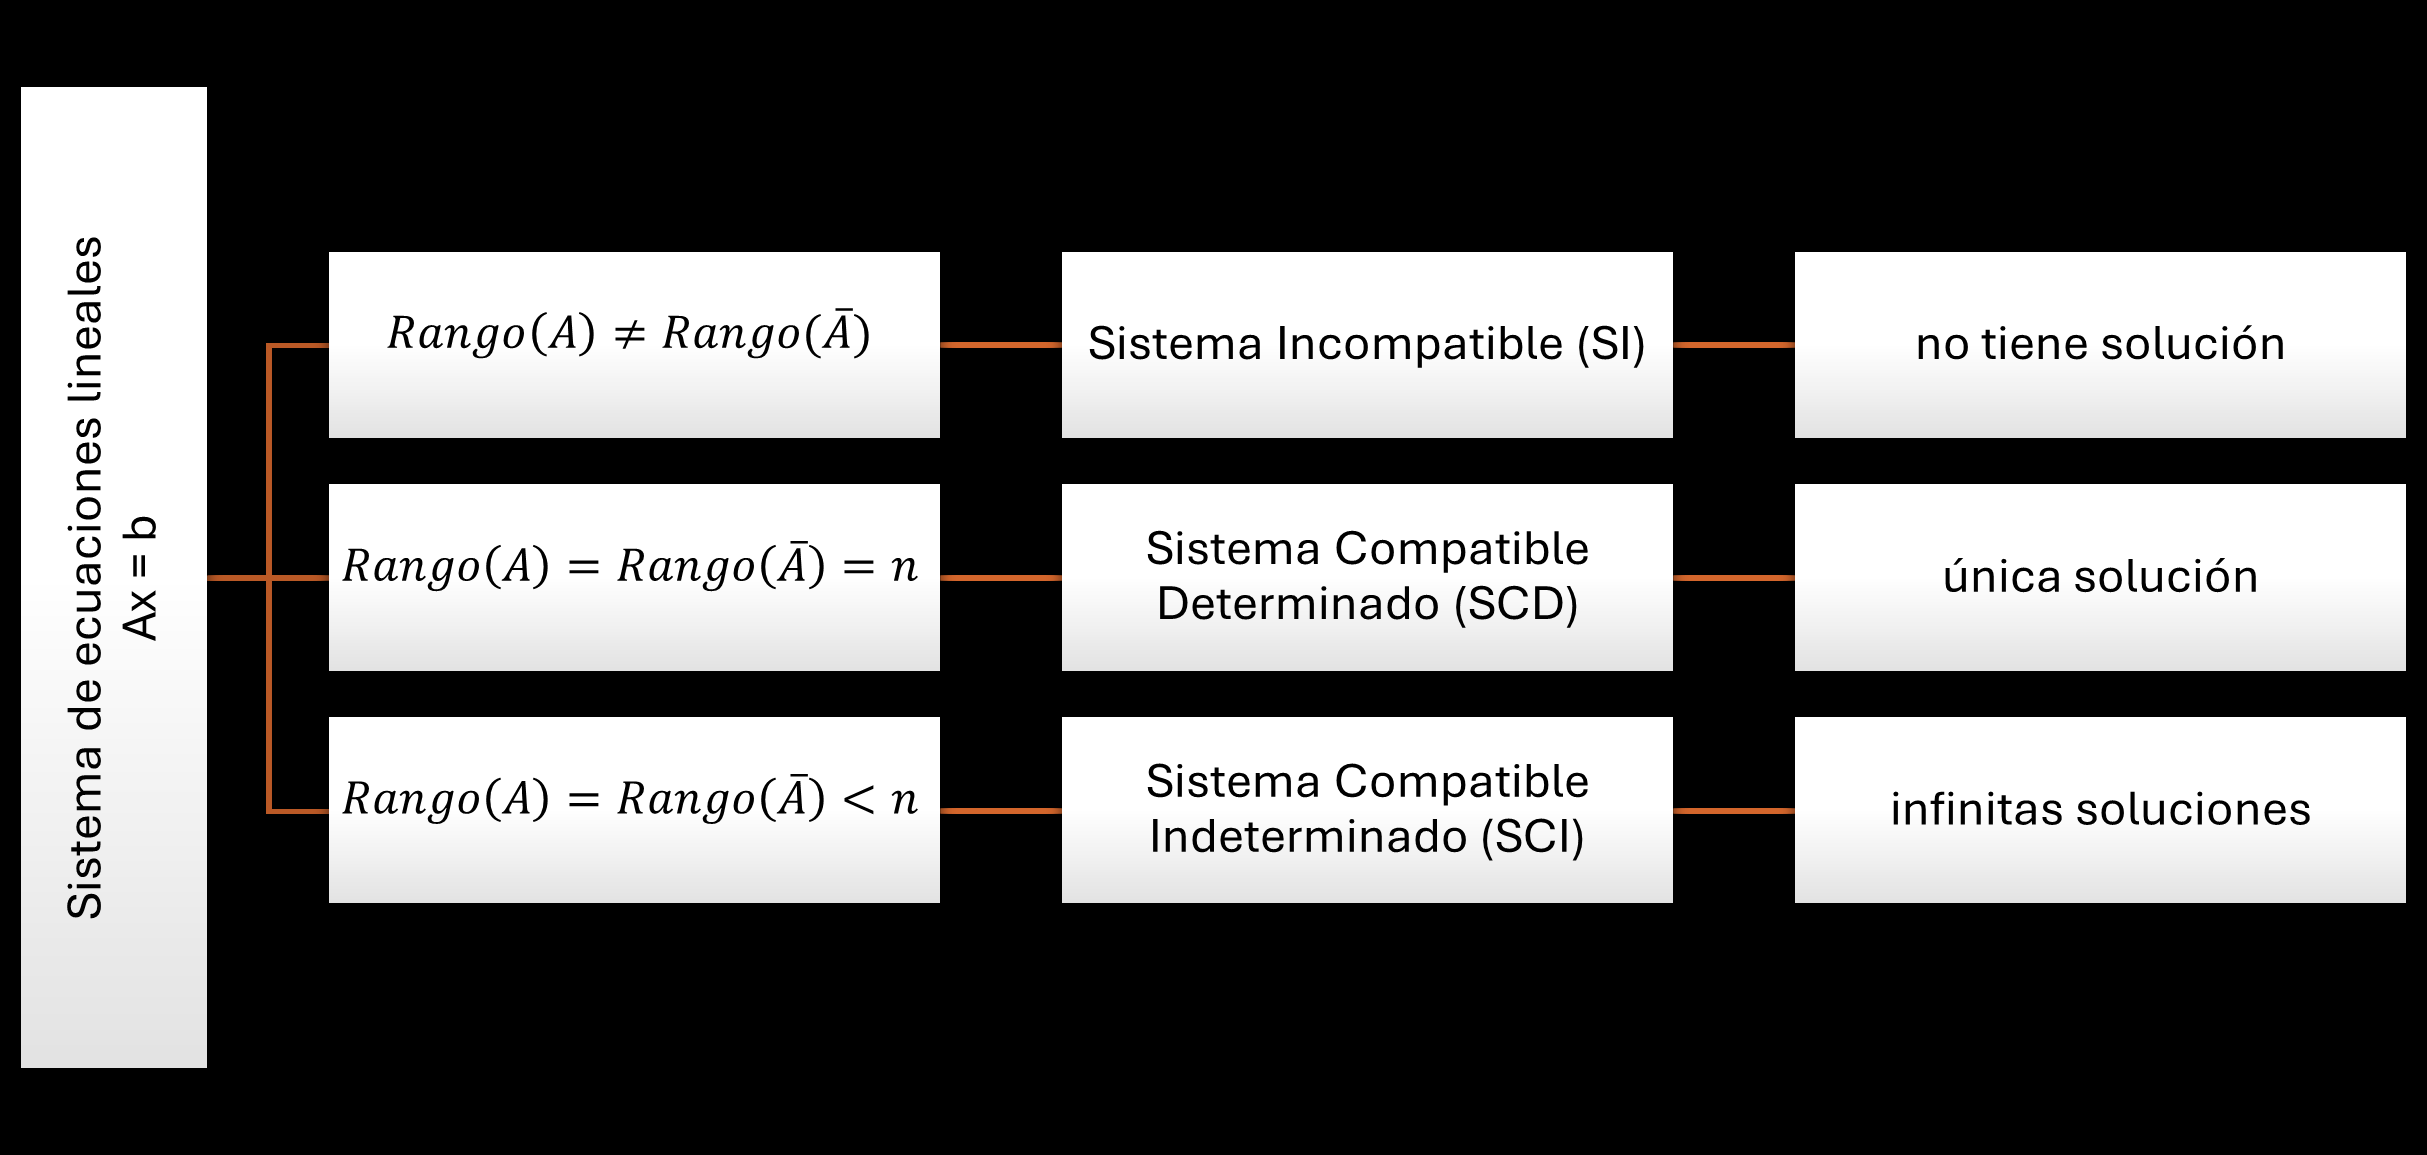

#### **Condicionamiento**

El número de condición es, de manera informal, una cantidad que nos permite medir cómo de sensible es la solución de un problema a perturbaciones en sus datos iniciales.

Consideramos el sistema

	
$$\[ Ax = b \]$$


pero existe una pequeña perturbación $$\delta b$$ en los datos del vector $$b$$. Esto nos lleva a que el vector solución $$x$$ también será perturbado por una cantidad $$\delta x$$ y el sistema será ahora

	
$$\[ A(x + \delta x) = b + \delta b \to Ax + A\delta x = b + \delta b  \to\;A\delta x = \delta b \]$$


	Del sistema original, sabemos que

	
$$\[ ||b|| = ||Ax|| \le ||A|| ||x|| \]$$


y del sistema perturbado sacamos que

	
$$\[ ||\delta x|| = ||A^{-1}\delta b|| \le ||A^{-1}|| ||\delta b|| \]$$


Luego combinando ambas desigualdades, tenemos que

	
$$\[ \frac{||\delta x||}{||x||} \le ||A|| ||A^{-1}|| \frac{||\delta b||}{||b||} \]$$


Llamamos **número de condición** a la cantidad

	
$$\[ \kappa(A) = ||A|| ||A^{-1}|| \]$$


 Para toda matriz A invertible se cumple:	

- 
$$$1 \le \kappa(A) < \infty $, $\quad\kappa(A) = \kappa(A^{-1})$,$$
			 

- 
$$$\kappa(\alpha A) = \kappa(A)$ para todo escalar $\alpha$.$$
			 

-  Cuanto más cercano a 1 sea el número de condición, más estable es la resolución numérica del sistema de ecuaciones.

-  Si el número de condición es $$10^k$$ con $$k \ge 1$$, entonces se espera que la solución del problema pierda $$k$$ dígitos de precisión.

-  Decimos que el problema está bien (o mal) condicionado si el número de condición es pequeño (o grande).

**Ejercicio (4.5): **Se tienen dos sistemas de ecuaciones, uno con la matriz P y otro con Q:


$$		P = 
		\left( \matrix{
			5 & 0 \cr
			0 & 4 
		}\right),
		\quad
		Q = 
			\left( \matrix{
			1 & 1 \cr
			1 & 1.0001 
		}\right)
		\]$$


Calcula el número de condición $$\kappa(P)$ y $\kappa(Q)$$ usando la norma infinito. ¿Cuál de los dos sistemas es numéricamente más estable (mejor condicionado) para resolver?

 % escribe aquí el código:





## Resolución numérica de sistemas lineales

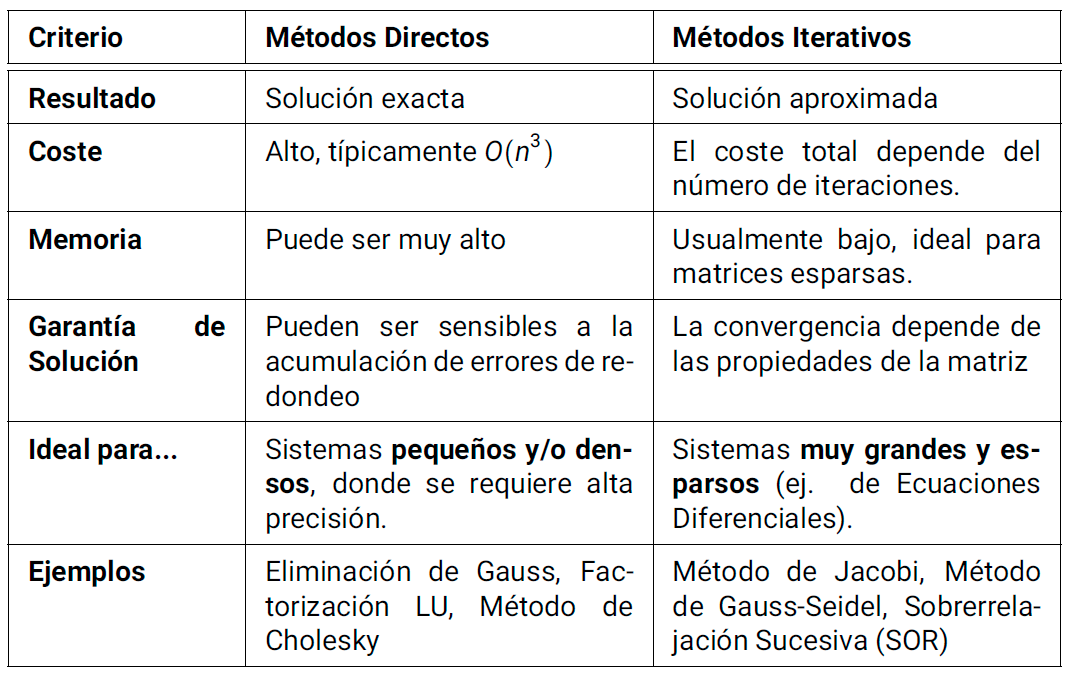

### Métodos directos

#### Eliminación gaussiana

Idea: Transformar un sistema de ecuaciones lineales $$A{x} = {b}$$ en un sistema equivalente y fácil de resolver, de forma triangular superior $$U{x} ={c}$$.

- Eliminación hacia adelante (Triangularización): Introducir ceros sistemáticamente debajo de la diagonal principal.

- Se trabaja con la matriz aumentada $$[A|\mathbf{b}]$$.

- El proceso se realiza en $$n-1$$ etapas.

- En cada etapa $$k$$ (para $$k=1, \dots, n-1$$) se elige el elemento $$a_{kk}^{(k)}$$ como **pivote**. Para cada fila $ $i$$ por debajo del pivote ($$i = k+1, \dots, n$$) se calcula el multiplicador: $$m_{ik} = \frac{a_{ik}^{(k)}}{a_{kk}^{(k)}}$$ y se actualiza la fila $$i$$ con la operación: $$F_i \leftarrow F_i - m_{ik} \cdot F_k$$			

			 El resultado es que todos los elementos$ $a_{ik}^{(k+1)}$$ con $$i>k$$ se hacen cero.

2. Sustitución regresiva: Resolver el sistema triangular superior resultante.

**Ejercicio (4.6)	: **Consideremos el sistema y su matriz aumentada:

	
$$\[
	\left[
	\begin{array}{ccc|c}
		{2} & 1 & -1 & 8 \\
		-3 & -1 & 2 & -11 \\
		-2 & 1 & 2 & -3
	\end{array}
	\right]
	\]$$


 clearvars
 A = [2 1 -1 8
     -3 -1 2 -11
     -2 1 2 -3]
 	

Elegimos el pivote: $$a_{11}=2$$:

 k = 1;
 p = A(k,k)

Calculamos el multiplicador: 

 m = A(k+1:end,k) / p % para i = k+1,...,n


$$F_i \leftarrow F_i - m_{ik} \cdot F_k$$:

 A(k+1:end,:) =  A(k+1:end,:)  - m.*A(k,:)

 Resultado de la Etapa 1:  $$\left[
		\begin{array}{ccc|c}
			2 & 1 & -1 & 8 \\
			{0} & 0.5 & 0.5 & 1 \\
			{0} & 2 & 1 & 5
		\end{array}
		\right]$$	

Ahora repetimos todo para $k=2$, pivote: $$a_{22}=0.5$$:

 k = 2;
 p = A(k,k);
 m = A(k+1:end,k) / p; % para i = k+1,...,n
 A(k+1:end,:) =  A(k+1:end,:)  - m.*A(k,:)

Resultado de la Etapa 2: $$
	\left[
	\begin{array}{ccc|c}
		2 & 1 & -1 & 8 \\
		0 & 0.5 & 0.5 & 1 \\
		 0 & {0} & -1 & 1
	\end{array}
	\right]$$

Fase 2: Sustitución Regresiva

Se resuelve de abajo hacia arriba:

 x = zeros(3,1);
 for k = 3:-1:1
     x(k) = (A(k,end) - A(k,k+1:end-1)*x(k+1:end)) / A(k,k);
 end
 x

	Solución Final: $$\mathbf{x} = [2, 3, -1]^T$$

 % para comprobar el resultado:

 A(:,1:end-1)*x  % debe ser igual al vector b

 % Ahora, implementa el método de Gauss completo:





¿Qué ocurre si el elemento pivote $$a_{kk}^{(k)}$$ es cero o muy cercano a cero?

- **Pivote Cero**: El cálculo del multiplicador $$m_{ik} = \frac{a_{ik}^{(k)}}{a_{kk}^{(k)}}$$ implica una **división entre cero**. El algoritmo falla.

- **Pivote Casi Cero:** La división por un número muy pequeño produce un multiplicador muy grande. Esto amplifica los errores de redondeo existentes y puede destruir la precisión de la solución.

**Solución: Estrategia de pivoteo parcial**

En cada etapa $$k$$, antes de calcular los multiplicadores:

-  Se busca el elemento de mayor valor absoluto en la columna $$k$$, desde la fila $$k$$ hacia abajo: $\[ |a_{pk}^{(k)}| = \max_{i=k, \dots, n} |a_{ik}^{(k)}| \]$		

- Se intercambia la fila $$k$$ con la fila $$p$$ (donde se encontró el máximo):	$\[ F_k \leftrightarrow F_p \]$

- Se realiza la eliminación como antes, usando el nuevo pivote (el más grande posible).

**Eejercicio (4.7):** Implementa el método de Gauss con el pivoteo parcial. Se recomienda usar el siguiente algoritmo:

 % escribe aquí el código






	**Conclusiones sobre Eliminación gaussiana**

	El número de operaciones de punto flotante (multiplicaciones y sumas) es:

		
$$$$\text{Coste} \approx \frac{2}{3}n^3 + O(n^2) \approx  O(n^3) $$$$


	Esto lo hace muy costoso para sistemas grandes.

- Transforma el sistema en uno triangular superior, que se resuelve fácilmente por sustitución regresiva.

- El pivoteo parcial es esencial para garantizar la estabilidad numérica y evitar fallos por división entre cero.

- Su alto coste computacional $(O(n^3))$ lo hace impráctico para sistemas muy grandes y esparsos.

- Sirve como base conceptual para otros métodos directos más avanzados, como la factorización LU.

#### Factorización LU

Idea: Factorizar la matriz A como el producto de dos matrices triangulares: una inferior (L) y una superior (U):  A = L U.

Una vez que tenemos A=LU, el sistema se convierte en $$LU\mathbf{x} = \mathbf{b}$$:

1.  Definimos un vector intermedio $$\mathbf{y}$$ tal que $$U\mathbf{x} = \mathbf{y}$$

2. Resolvemos el sistema triangular inferior para $$\mathbf{y}$$: $$ {L\mathbf{y} = \mathbf{b}} $, esto es rápido ($O(n^2)$).$

3. Resolvemos el sistema triangular superior para $$\mathbf{x}$$: $${U\mathbf{x} = \mathbf{y}}$, esto también es rápido ($O(n^2)$

**¿De dónde vienen L y U?**


$$$$L = 
\left(\matrix{
	1 & 0 & 0 \cr
	\ell_{21} & 1 & 0 \cr
	\ell_{31} & \ell_{32} & 1
}\right), \quad 	U =
\left(\matrix{
	u_{11} & u_{12} & u_{13} \cr
	0 & u_{22} & u_{23} \cr
	0 & 0 & u_{33}
}\right)$$$$


- La matriz U es simplemente la matriz triangular superior que obtenemos al final de la fase de eliminación hacia adelante.

- La matriz L es una matriz triangular inferior con unos en la diagonal, que almacena en su parte inferior los multiplicadores $$m_{ik}$$ que usamos en cada paso de la eliminación.

La factorización LU no es un método nuevo, sino una reorganización inteligente de la eliminación gaussiana que guarda los resultados de forma estructurada.

La factorización LU simple puede fallar o ser numéricamente inestable por la misma razón que la eliminación gaussiana básica: un pivote nulo o pequeño.

En la práctica, casi siempre se usa el pivoteo parcial. Esto es equivalente a reordenar las filas de A antes de la factorización.

Se introduce una **matriz de permutación** P que registra todos los intercambios de filas.

			 La descomposición robusta es: $$\mathbf{PA = LU}$$.

Proceso de solución con pivoteo: 

- 
$$$A\mathbf{x}=\mathbf{b} \to PA\mathbf{x} = P\mathbf{b} \to LU\mathbf{x} = P\mathbf{b}$$$


- Resolver $$L\mathbf{y} = P\mathbf{b}$$.

- Resolver $$U\mathbf{x} = \mathbf{y}$$.

#### Métodos directos en MATLAB

Para resolver $$A\mathbf{x} = \mathbf{b}$$, el comando más eficiente y recomendado es:

Esto NO es lo mismo que `inv(A)*b`. Calcular la inversa explícitamente es más costoso y numéricamente menos estable.

**Factorización LU**

Esto calcula la descomposición $\textbf{$PA=LU$}$. Luego, podrías resolver el sistema manualmente:

#### Conclusiones

-  La convergencia de ambos métodos está **garantizada**.

-  La factorización LU es una representación matricial de la eliminación gaussiana.

- Su principal ventaja es la eficiencia para resolver sistemas $$A\mathbf{x}=\mathbf{b}$ $con la misma matriz A y múltiples vectores $$\mathbf{b}$$.

- Otra ventaja de la factorización LU es que permite calcular fácilmente el determinante de una matriz dada. Si consideramos la factorización LU de la matriz A:


$$\[ A = LU \]$$


               por propiedades de determinantes, sabemos que

				
$$\[ \det(A) = \det(L)\det(U) = \det(U) = u_{11} \cdots u_{nn} \]$$


				(ya que $ $\det(L) = 1$$ por construcción).

**Ejercicios (4.8) -(4.9)**

% escribe aquí el código



### Métodos iterativos

Limitaciones de los Métodos Directos (Gauss, LU):

- **Coste Computacional**:  La complejidad de $$O(n^3)$ $los hace inviables para sistemas muy grandes ($$n > 10^5$$).

- **Almacenamiento y "Fill-in"**: Si la matriz A es* esparsa (*tiene muchos ceros), la eliminación gaussiana puede destruir esa estructura llenando la matriz de elementos no nulos ("fill-in"), lo que consume mucha memoria.

Idea de los métodos iterativos: Transformar el sistema $$A\mathbf{x} = \mathbf{b}$$ en una forma equivalente de punto fijo:

		
$$\[ \mathbf{x} = T\mathbf{x} + \mathbf{c} \]$$


donde T es la **matriz de iteración** y $$\mathbf{c}$$ es un vector.

**Condición necesaria y suficiente de convergencia:**

		La iteración $$\mathbf{x}^{(k+1)} = T\mathbf{x}^{(k)} + \mathbf{c}$$ converge a la solución única para cualquier vector inicial $$\mathbf{x}^{(0)}$$ si y solo si el radio espectral de T es menor que 1:

		
$$\[{\rho(T) < 1} \]$$


donde $$\rho(T) = \max_i |\lambda_i|$$ es el valor propio (autovalor) de mayor magnitud de T.

**Condición suficiente (más fácil de verificar):**

		Si la matriz original $$A_{n\times n}$$ es estrictamente diagonal dominante,

		
$$$$|a_{kk}| > \sum_{j=1, j\neq k}^n |a_{kj}|, \quad k = 1,2,\ldots, n, $$$$


entonces los métodos de Jacobi y Gauss-Seidel convergen.

#### Método de Jacobi

 En la ecuación $i$-ésima del sistema, $$\sum_{j=1}^n a_{ij}x_j = b_i$$, se despeja la variable $$x_i$$ y se usan los valores del paso anterior para las demás variables.

	Sea el sistema

	
$$\[
	\begin{cases}
		a_{11}x_1 + a_{12}x_2 + \dots + a_{1n}x_n = b_1 \\
		a_{21}x_1 + a_{22}x_2 + \dots + a_{2n}x_n = b_2 \\
		\vdots \\
		a_{n1}x_1 + a_{n2}x_2 + \dots + a_{nn}x_n = b_n
	\end{cases}
	\]$$


	consideramos las fórmulas de iteración:

	
$$\[
	\begin{cases}
		x_1^{(k+1)} = \frac{1}{a_{11}}(b_1 - a_{12}x_2^{(k)} - \dots - a_{1n}x_n^{(k)}) \\
		x_2^{(k+1)} = \frac{1}{a_{22}}(b_2 - a_{21}x_1^{(k)} - \dots - a_{2n}x_n^{(k)}) \\
		\vdots \\
		x_n^{(k+1)} = \frac{1}{a_{nn}}(b_n - a_{n1}x_1^{(k)} - \dots - a_{n(n-1)}x_{n-1}^{(k)})
	\end{cases}
	\]$$


Entonces, las iteraciones para cada $x_i$, $i = 1, \ldots, n$:

		
$$ x_i^{(k+1)} = \frac{1}{a_{ii}} \left( b_i - \sum_{j=1, j\neq i}^{n} a_{ij}x_j^{{(k)}} \right) \]$$


Se necesitan dos vectores en memoria: uno para $$\mathbf{x}^{(k)}$$ y otro para $$\mathbf{x}^{(k+1)}$$.

El método de Jacobi también se puede interpretar de forma matricial:


$$\[ x^{(k+1)} = J x^{(k)} + D^{-1}b \]$$


donde D es la matriz diagonal de A, y $$J = -D^{-1}(A-D)$$:


$$\[
J = 
\left(\matrix{
	0 & -a_{12}/a_{11} & \dots & -a_{1n}/a_{11} \cr
	-a_{21}/a_{22} & 0 & \dots & -a_{2n}/a_{22} \cr
	\vdots & \vdots & \ddots & \vdots \cr
	-a_{n1}/a_{nn} & -a_{n2}/a_{nn} & \dots & 0
}\right)
\]$$


**Ejercicio (4.10)**

Utilizando el método de Jacobi, calcula tres iteraciones para el siguiente sistema, empezando desde el vector nulo $$\mathbf{x}^{(0)} = (0,0,0)^T$$. ¿Converge la iteración?


$$$$\begin{cases}
	4x-y+z = 7\\
	4x - 8y +z = -21\\
	-2x+y+5 = 15
\end{cases}$$$$


clearvars
A = [4 -1 1
    4 -8 1
    -2 1 5];
b = [7; -21; 15];


 1. Convergencia:

- Fila 1: $$|4| > |-1| + |1| \to 4 > 2$ $(Se cumple)

- Fila 2: $$|-8| > |4| + |1| \to 8 > 5$$ (Se cumple)

- Fila 3: $$|5| > |-2| + |1| \to5 > 3$$ (Se cumple)

Como la condición se cumple para todas las filas, la matriz es estrictamente diagonal dominante. Por lo tanto, el método de Jacobi convergerá a la solución única del sistema, sin importar el punto de partida.	

2. Fórmulas de Iteración de Jacobi

Despejamos cada variable de una ecuación distinta:

	
$$\[
\begin{cases}
	4x-y+z = 7\\
	4x - 8y +z = -21\\
	-2x+y+5 = 15
\end{cases} \to	\begin{cases}
		x^{(k+1)} &= \frac{1}{4} (7 + y^{(k)} - z^{(k)}) \\
		y^{(k+1)} &= \frac{1}{8} (21 + 4x^{(k)} + z^{(k)}) \\
		z^{(k+1)} &= \frac{1}{5} (15 + 2x^{(k)} - y^{(k)})
	\end{cases}
	\]$$


3. Cálculo de iteraciones:

Comenzamos con el vector nulo: $$\mathbf{x}^{(0)} = (x^{(0)}, y^{(0)}, z^{(0)})^T = (0, 0, 0)^T$$.

n = 3;
x = zeros(n,1);     % aproximación inicial


Iteración 1 (k=0):  

xk = x; 
for i = 1:n
    % Calcula la suma de los productos A(i,j) * xk(j) para j != i
    suma = A(i, :) * xk - A(i, i) * xk(i);

    % Calcula el nuevo valor para x(i)
    x(i) = (b(i) - suma) / A(i, i);
end
x

$$\mathbf{x}^{(1)} = (1.75, 2.625, 3)^T$$.	

Iteración 2 (k=1): 

xk = x; 
for i = 1:n
    % Calcula la suma de los productos A(i,j) * xk(j) para j != i
    suma = A(i, :) * xk - A(i, i) * xk(i);

    % Calcula el nuevo valor para x(i)
    x(i) = (b(i) - suma) / A(i, i);
end
x


$$ $\mathbf{x}^{(2)} = (1.65625, 3.875, 3.175)^T$.$$


Iteración 3 (k=2):

xk = x; 
for i = 1:n
    % Calcula la suma de los productos A(i,j) * xk(j) para j != i
    suma = A(i, :) * xk - A(i, i) * xk(i);

    % Calcula el nuevo valor para x(i)
    x(i) = (b(i) - suma) / A(i, i);
end
x


$$ $\mathbf{x}^{(3)} = (1.925, 3.85, 2.8875)^T$$$


Y así podemos continuar... ¿hasta cuándo?

**Criterios de parada:**

Se detiene cuando la diferencia entre dos iteraciones sucesivas es suficientemente pequeña:

		
$$\[ \frac{\|\mathbf{x}^{(k+1)} - \mathbf{x}^{(k)}\|}{\|\mathbf{x}^{(k+1)}\|} < \varepsilon \quad \text{(Error relativo)} \]$$


		o

		
$$\[ \|\mathbf{x}^{(k+1)} - \mathbf{x}^{(k)}\| < \varepsilon \quad \text{(Error absoluto)} \]$$


Siempre se debe incluir un número máximo de iteraciones para evitar bucles infinitos si el método no converge.

**Ejercicio (4.11)**

Expresa los sistemas planteados en el ejercicio (4.10) en su forma matricial. A continuación, implementa el algoritmo de Jacobi para hallar la solución numérica.

% escribe aquí el código:




#### Método de Gauss-Seidel

Cuando calculamos $$x_i^{(k+1)}$$, ya hemos calculado los nuevos valores $$x_1^{(k+1)}, \dots, x_{i-1}^{(k+1)}$$. ¿Por qué no usarlos inmediatamente?

**Método de Gauss-Seidel:**

		
$$\[  x_i^{(k+1)} = \frac{1}{a_{ii}} \left( b_i - \sum_{j=1}^{i-1} a_{ij}x_j^{{(k+1)}} - \sum_{j=i+1}^{n} a_{ij}x_j^{{(k)}} \right) \]$$


Solo se necesita un vector en memoria, ya que los valores se sobrescriben.

Generalmente, si converge, lo hace más rápido que Jacobi.

**Forma Matricial:**

Se descompone $$A = D - L - U$$ (Diagonal, Triangular Inferior, Triangular Superior). La matriz de iteración de Gauss-Seidel es:

	
$$	\[ T_{GS} = (D-L)^{-1}U \]$$


**Ejercicio (4.12)**

Utilizando el método de Gauss-Seidel, calcula tres iteraciones para el siguiente sistema, empezando desde el vector nulo $$\mathbf{x}^{(0)} = (0,0,0)^T$$. ¿Converge la iteración?

		
$$$$\begin{cases}
			4x-y+z = 7\\
			4x - 8y +z = -21\\
			-2x+y+5 = 15
		\end{cases}$$$$


clearvars
A = [4 -1 1
    4 -8 1
    -2 1 5];
b = [7; -21; 15];


1. Convergencia: El método converge ya que la matriz es estrictamente diagonal dominante.	

2. Fórmulas de Iteración

	
$$\[
	\begin{cases}
		x^{(k+1)} &= \frac{1}{4} (7 + y^{(k)} - z^{(k)}) \\
		y^{(k+1)} &= \frac{1}{8} (21 + 4{x^{(k+1)}} + z^{(k)}) \\
		z^{(k+1)} &= \frac{1}{5} (15 + 2{x^{(k+1)}} - {y^{(k+1)}})
	\end{cases}
	\]$$


3. Cálculo de iteraciones:

Comenzamos con el vector nulo: $\mathbf{x}^{(0)} = (x^{(0)}, y^{(0)}, z^{(0)})^T = (0, 0, 0)^T$.

n = 3;
x = zeros(n,1);     % aproximación inicial

Iteración 1 (k=0): 

for i = 1:n
    suma = A(i, :) * x - A(i, i) * x(i);
    x(i) = (b(i) - suma) / A(i, i);
end
x


$$$\mathbf{x}^{(1)} = (1.75, 3.5, 3)^T$.$$


Iteración 2 (k=1): 

for i = 1:n
    suma = A(i, :) * x - A(i, i) * x(i);
    x(i) = (b(i) - suma) / A(i, i);
end
x


$$ $\mathbf{x}^{(2)} = (1.875, 3.9375, 2.9625)^T$.$$


Iteración 3 (k=2): 

for i = 1:n
    suma = A(i, :) * x - A(i, i) * x(i);
    x(i) = (b(i) - suma) / A(i, i);
end
x


$$$\mathbf{x}^{(3)} = (1.99375, 3.9921875, 2.9990625)^T$.	$$


**Comparación de los métodos iterativos**

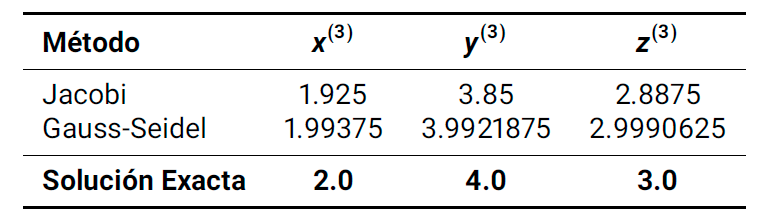

- Ambos métodos convergen hacia la solución, como se esperaba, ya que la matriz es estrictamente diagonal dominante.

- Tras solo tres iteraciones, se observa claramente que la aproximación obtenida con el método de Gauss-Seidel está significativamente más cerca de la solución exacta que la obtenida con el método de Jacobi.

#### Métodos iterativos en MATLAB

Métodos clásicos (Jacobi y Gauss-Seidel) son  excelentes para aprender y muy fáciles de implementar, pero a menudo son demasiado lentos o su convergencia es muy limitada para ser usados en software profesional. 

	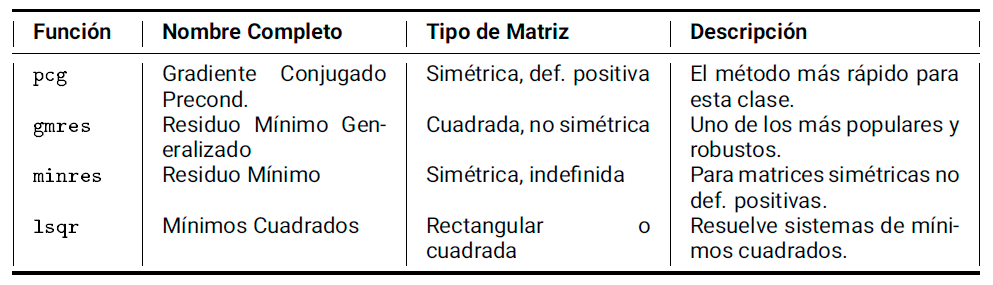

La sintaxis para usar estos métodos es muy similar entre ellos:

- 		 A: La matriz de coeficientes

- 		 b: El vector de términos independientes.

- 		 tol: (Opcional) La tolerancia del error. Por defecto es $1e-6$.

- 		 maxit: (Opcional) El número máximo de iteraciones.

- 		 x0: (Opcional) La estimación inicial de la solución.

	**Ejemplo: **Sistema de los ejercicios (4.10)-(4.12)

clearvars
A = [4 -1 1
    4 -8 1
    -2 1 5];
b = [7; -21; 15];
x0 = zeros(3,0);
x = gmres(A, b, x0)

### Conclusiones: Directos vs. Iterativos

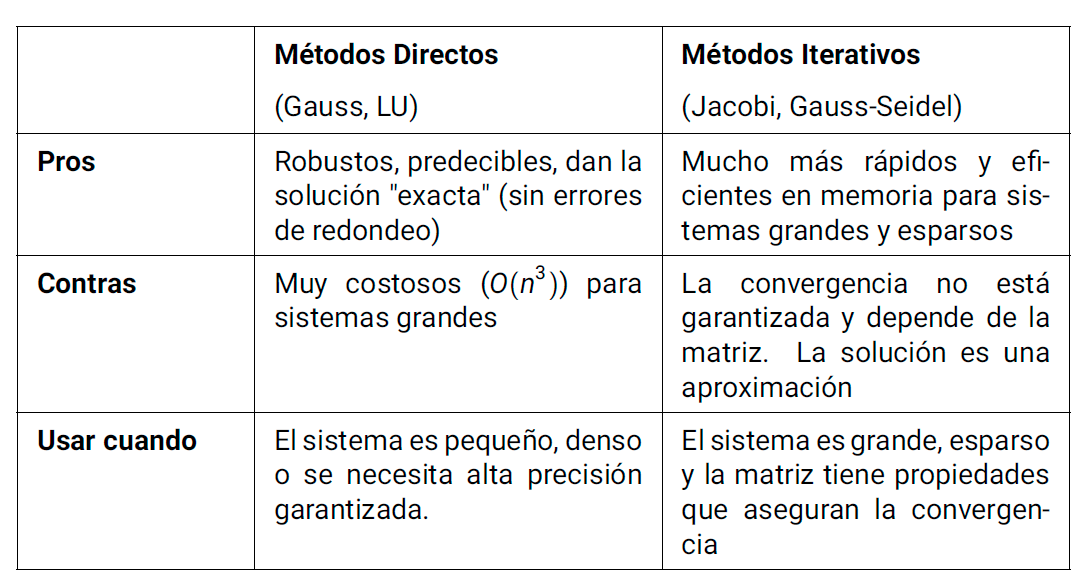

## Autovalores y autovectores

		Dado una matriz cuadrada $$A \in \mathbb{C}^{n \times n}$$, un escalar $$\lambda$$ es un **autovalor** de A si existe un vector no nulo $$\mathbf{v}$$ (su autovector} asociado) tal que:

		
$$\[  A\mathbf{v} = \lambda\mathbf{v} \]$$


Aplicaciones:	

- Física: Frecuencias de vibración de un sistema mecánico.

- Estabilidad: Análisis de sistemas dinámicos y ecuaciones diferenciales.

- Ciencia de Datos: Componentes Principales (PCA), PageRank de Google.

	Los autovalores son las raíces de la ecuación característica: $$\det(A - \lambda I) = 0$$.

- 	 Para matrices grandes, calcular el determinante y encontrar las raíces del polinomio es computacionalmente prohibitivo y numéricamente inestable.

- 	 No hay fórmulas generales para raíces de polinomios de grado $$\ge 5$$.

Conclusión: Necesitamos métodos numéricos iterativos.

**Desafíos en el cálculo de autovalores**

El cálculo de autovalores puede ser un problema mal condicionado. Pequeños cambios en la matriz pueden causar grandes cambios en los autovalores.

**Ejemplo: **Sean dos matrices $$A$  y $A'$$:

		
$$\[ A = \left(\matrix{ 0 & 1 \cr 0 & 0 }\right), \quad A' = \left(\matrix{  0 & 1 \cr \epsilon & 0 }\right)  \]
	$$


- Los autovalores de A son $$\lambda_1 =\lambda_2 = 0$$.

- Los autovalores de  $$A'$$ son $$\lambda' = \pm\sqrt{\epsilon}$$

Imaginemos que $$\epsilon = 10^{-16}$$ :

clearvars
format shorte
epsilon = 1e-16
A =[0 1
    0 0]
A1 = [0 1
    epsilon 0]	

% Calculamos autovalores:
autivalores_A = eig(A)
autivalores_A1 =eig(A1)

- Cambio en la matriz: $${10^{-16}}$$.

- Los nuevos autovalores: $$\lambda' = \pm\sqrt{10^{-16}} = {\pm 10^{-8}}$$.

Este es un problema extremadamente mal condicionado. La causa es la estructura no simétrica con autovalores repetidos. Las matrices simétricas no sufren de este problema tan severo.

#### Círculos de Gerschgorin

**Teorema de Gerschgorin: **Todos los autovalores de una matriz A se encuentran en la unión de n discos en el plano complejo, definidos por:

		
$$\[ D_i = \left\{ z \in \mathbb{C} : |z - a_{ii}| \le \sum_{j \neq i} |a_{ij}| \right\} \]$$


Para cada fila $i$:

- El **centro** del círculo es el elemento de la diagonal $$a_{ii}$$.

- El **radio **es la suma de los valores absolutos de los demás elementos de esa fila.		

**Ejercicio (4.13)**

Utiliza el Teorema de Gerschgorin para estimar la localización de los autovalores de la matriz

	
$$$$A = \left(\matrix{ 4 & -1 & 0 \cr 1 & 1 & 1 \cr 0 & 2 & -2}\right)$$$$


clearvars
A = [4 -1 0
    1 1 1
    0 2 -2]

% Fila 1:
 i = 1;
centro = A(i,i)
radio = sum(abs(A(i,:)))-abs(centro)
intervalo = [centro - radio, centro+radio]

% Así podemos repetir para todas filas:
for i = 2:size(A,1)
    centro = A(i,i);
    radio = sum(abs(A(i,:)))-abs(centro);
    intervalo = [intervalo; centro - radio, centro+radio];
end

intervalo

Entonces, todos los autovalores están en la unión de los intrevalos:

circ_gershgorin= [min(intervalo(:,1)), max(intervalo(:,2))]

 Todos los autovalores están en [-4, 5].

#### Cálculo de autovalores en MATLAB

MATLAB ofrece la función `eig `para calcular autovalores y autovectores. Tiene dos formas de uso principales:

Para matrices grandes y/o esparsas, se usa `eigs`:

**Ejercicios (4.14)-(4.15)**

 % escribe aquí el código




## Bibliografía

- [Chapra S.C.; Canale R. (2015) Métodos Numéricos para Ingenieros. Ed. McGRaw-Hill](https://catalogo.unican.es/cgi-bin/abnetopac?TITN=436963) (Capítulos 9-11)

- [Mathews J.H., Fink K.D. (2000) Métodos Numéricos con MATLAB. Ed. Prentice Hall](https://catalogo.unican.es/cgi-bin/abnetopac?TITN=163396) (Capítulos 3 y 6)